% Initialization
close all
clear
clc

% Symbolic variables
syms x y t n_x n_y real
X=[x,y];
n=[n_x;n_y];

% Parameters
syms epsilon_p rho_1 rho_2 g_x g_y real
g=[g_x;g_y];

% Analytical solution
P=1-x;
S=0.8*(t-1)*x+0.9;

% Saturation-dependent parameters
K11=[  1-S      0
        0      1-S  ];
K12=[   0       0
        0       0   ];
K21=[   0       0
        0       0   ];
K22=[   S       0
        0       S   ];
G=1-2*S;

% Sources
q1=-rho_1*((4*t)/5-4/5)*(g_x*rho_1-(8*t)/5+13/5)-(4*epsilon_p*rho_1*x)/5;
q2=+rho_2*((4*t)/5-4/5)*((8*t)/5+g_x*rho_2-3/5)+(4*epsilon_p*rho_2*x)/5;

% Normal momentum
f1=-rho_1*dot((K11*(-mygradient(P,X)'+mygradient(G,X)'+rho_1*g)+...
               K12*(-mygradient(P,X)'-mygradient(G,X)'+rho_2*g)),n);
f2=-rho_2*dot((K21*(-mygradient(P,X)'+mygradient(G,X)'+rho_1*g)+...
               K22*(-mygradient(P,X)'-mygradient(G,X)'+rho_2*g)),n);

% Check residual 1
R1=simplify(...
   -epsilon_p*diff(rho_1*S,t)...
   +mydivergence(rho_1*(K11*(-mygradient(P,X)'+mygradient(G,X)'+rho_1*g)+...
                        K12*(-mygradient(P,X)'-mygradient(G,X)'+rho_2*g)),X)...
   -q1)

$$R1 = 0$$


% Check residual 2
R2=simplify(...
   +epsilon_p*diff(rho_2*S,t)...
   +mydivergence(rho_2*(K21*(-mygradient(P,X)'+mygradient(G,X)'+rho_1*g)+...
                        K22*(-mygradient(P,X)'-mygradient(G,X)'+rho_2*g)),X)...
   -q2)

$$R2 = 0$$

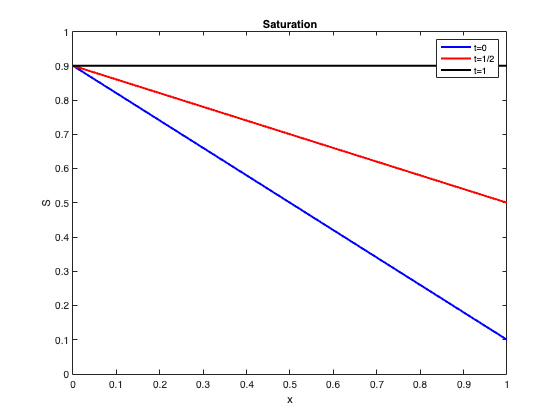


% Numerical values
epsilon_p=1/2; rho_1=1; rho_2=1; g=[0;0];

% Plot saturation
figure
fplot(x,subs(eval(S),t,  0),[0,1],'b','LineWidth',2)
hold on
fplot(x,subs(eval(S),t,1/2),[0,1],'r','LineWidth',2)
fplot(x,subs(eval(S),t,  1),[0,1],'k','LineWidth',2)
hold off
xlim([0,1])
ylim([0,1])
title('Saturation')
xlabel('x')
ylabel('S')
legend({'t=0','t=1/2','t=1'})